# 実験Ⅳ－１　線形単回帰モデル

`新潟大学工学部工学科　電子情報通信プログラム `

## `観測データ（ノイズなし）`

% 観測点数
nSamples = 2;

% 出力電流
current_observations = rand(nSamples,1);

% 負荷電圧
load_voltages = load_voltage(current_observations);


## `散布図の表示`

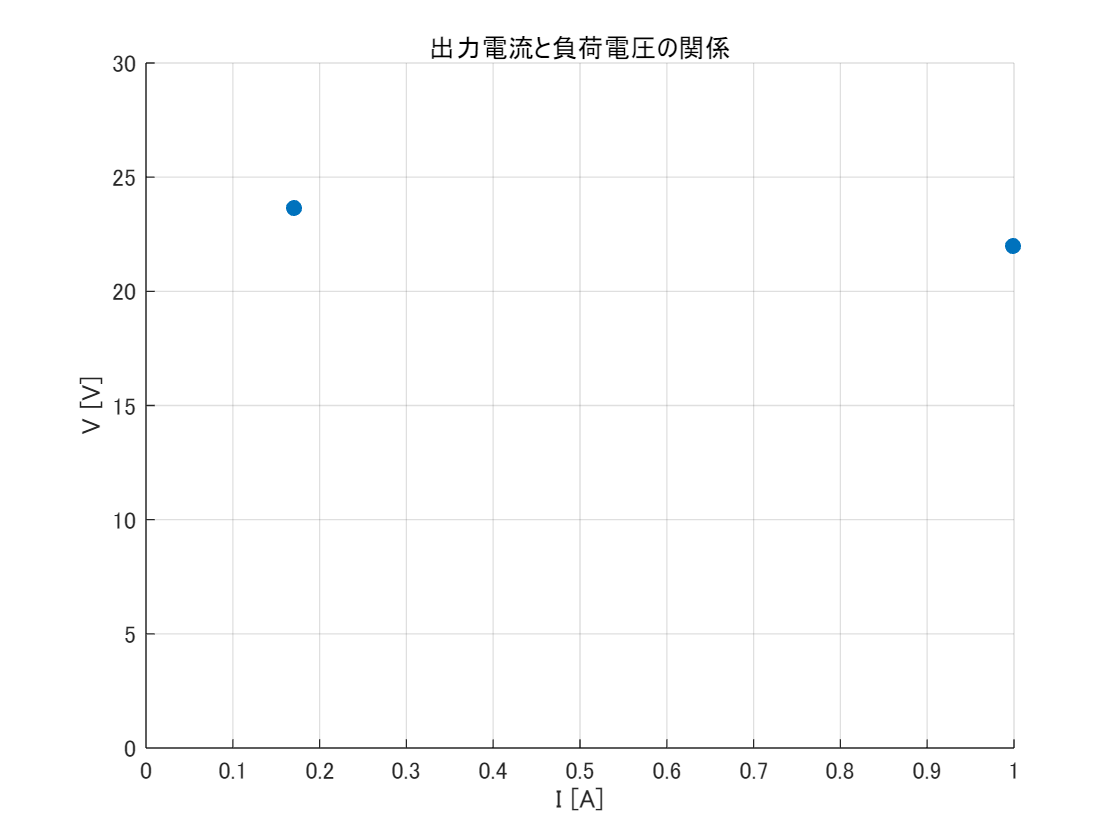

% 散布図の表示
figure
ax = gca;
scatter(current_observations,load_voltages,'filled')
title("出力電流と負荷電圧の関係");
xlabel("I [A]");
ylabel("V [V]");
ax.XLim = [0,1];
ax.YLim = [0,30];
grid on

drawnow

## `電源電圧 `$E$` と内部抵抗 `$r$` の解`

`連立方程式は、バックスラッシュ(\)で解くことができる。`

`データセット `$\{(\mathrm{I}_1,\mathrm{V}_1),\mathrm{I}_2,\mathrm{V}_2)\}$`より，`


$$\left(\begin{array}{l}E \\ r\end{array}\right)=\left(\begin{array}{ll}1 & -\mathrm{I}_{1} \\ 1 & -\mathrm{I}_{2}\end{array}\right)^{-1}\left(\begin{array}{l}\mathrm{V}_{1} \\ \mathrm{V}_{2}\end{array}\right)$$


X = [
    1., -current_observations(1)
    1., -current_observations(2)
    ];
y = load_voltages;
beta = X\y;

fprintf("電源電圧 E = %5.2f [V]",beta(1))

電源電圧 E = 24.00 [V]

fprintf("内部抵抗 r = %5.2f [Ω]",beta(2))

内部抵抗 r =  2.00 [Ω]

## `観測データ（ノイズあり）`

% 観測点数
nSamples = 8;

% 出力電流
current_observations = rand(nSamples,1);

% 観測誤差
nsigma = 0.5;
noise = nsigma*randn(nSamples,1);

% 負荷電圧
load_voltages = load_voltage(current_observations)+noise;

% 観測データの表
dataset = table(current_observations, load_voltages, 'VariableNames',{'I[A]','V[V]'});
disp(dataset)

      I[A]       V[V] 
    ________    ______

    0.032601    23.504
      0.5612     23.27
     0.88187    22.391
     0.66918    22.545
     0.19043    23.091
     0.36892     23.12
     0.46073    23.035
     0.98164    21.302



## `散布図の表示`

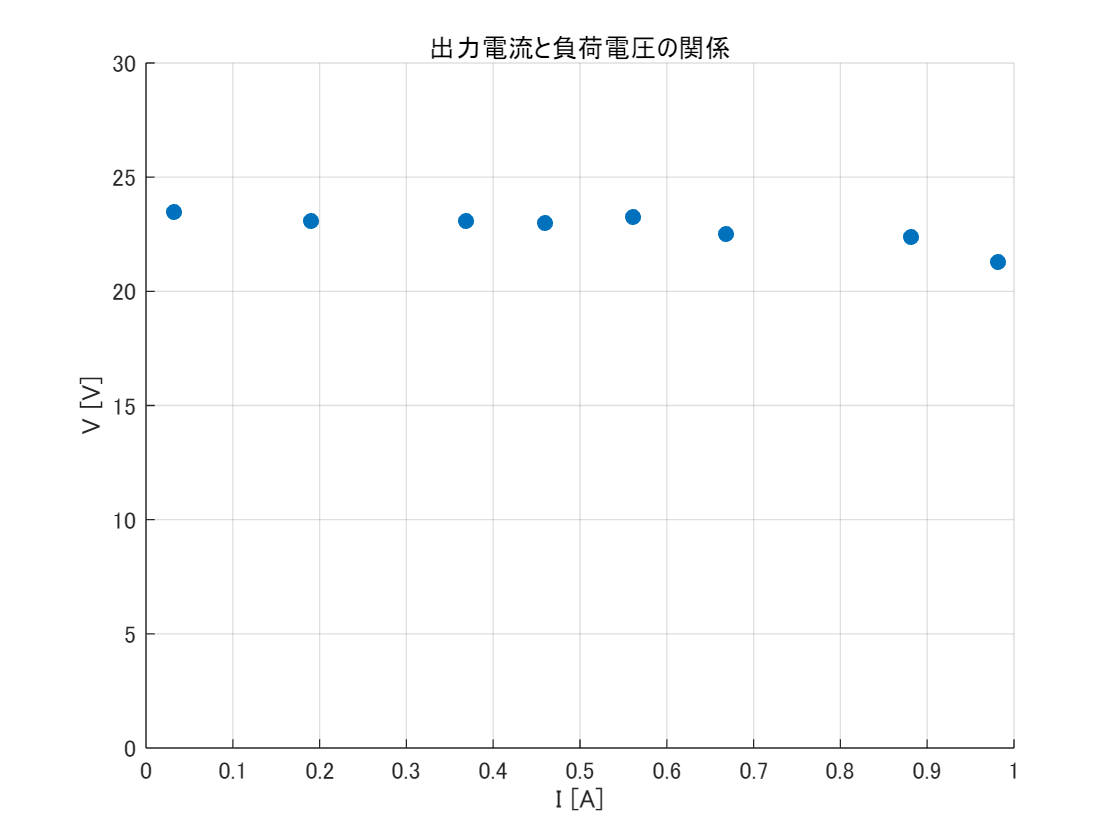

% 散布図の表示
figure
ax = gca;
scatter(current_observations,load_voltages,'filled')
title("出力電流と負荷電圧の関係");
xlabel("I [A]");
ylabel("V [V]");
ax.XLim = [0,1];
ax.YLim = [0,30];
grid on

drawnow

## `電源電圧 `$E$` と内部抵抗 `$r$` の推定`

`線形単回帰分析は、Scikit-learn ライブラリにあるsklearn.linear_model で計算できる。`


$$\left(\begin{array}{c} \hat{E} \\ \widehat{r} \end{array}\right)=\left(\begin{array}{cc} N & \sum_{i=1}^{N} I_{i} \\ \sum_{i=1}^{N} I_{i} & \sum_{i=1}^{N} I_{i}^{2} \end{array}\right)^{-1}\left(\begin{array}{c}\sum_{i=1}^{N} V_{i}\\\sum_{i=1}^{N} I_iV_{i}\end{array}\right)=\left(\mathbf{X} \mathbf{X}^{T}\right)^{-1} \mathbf{X}^{T} \mathbf{y}=\mathbf{X}^{+} \mathbf{y}$$


`ただし、`


$$\mathbf{X}=\left(\begin{array}{cc}1 & \mathrm{I}_{1} \\1 & \mathrm{I}_{2} \\\vdots & \vdots \\1 & \mathrm{I}_{N}\end{array}\right), \quad \mathbf{y}=\left(\begin{array}{c}\mathrm{V}_{1} \\\mathrm{V}_{2} \\\vdots \\\mathrm{y}_{N}\end{array}\right)$$


% 説明変数の設定
x = dataset.('I[A]');

% 目的変数の設定
y = dataset.('V[V]');

% 回帰分析
reg = fit(x,y,'poly1');

%  推定結果
Ehat = reg.p2;
rhat = -reg.p1;
fprintf("電源電圧の推定値 E^ = %5.2f [V]",Ehat)

電源電圧の推定値 E^ = 23.73 [V]

fprintf("内部抵抗の推定値 r^ = %5.2f [Ω]",rhat)

内部抵抗の推定値 r^ =  1.84 [Ω]

## 回帰直線をプロット

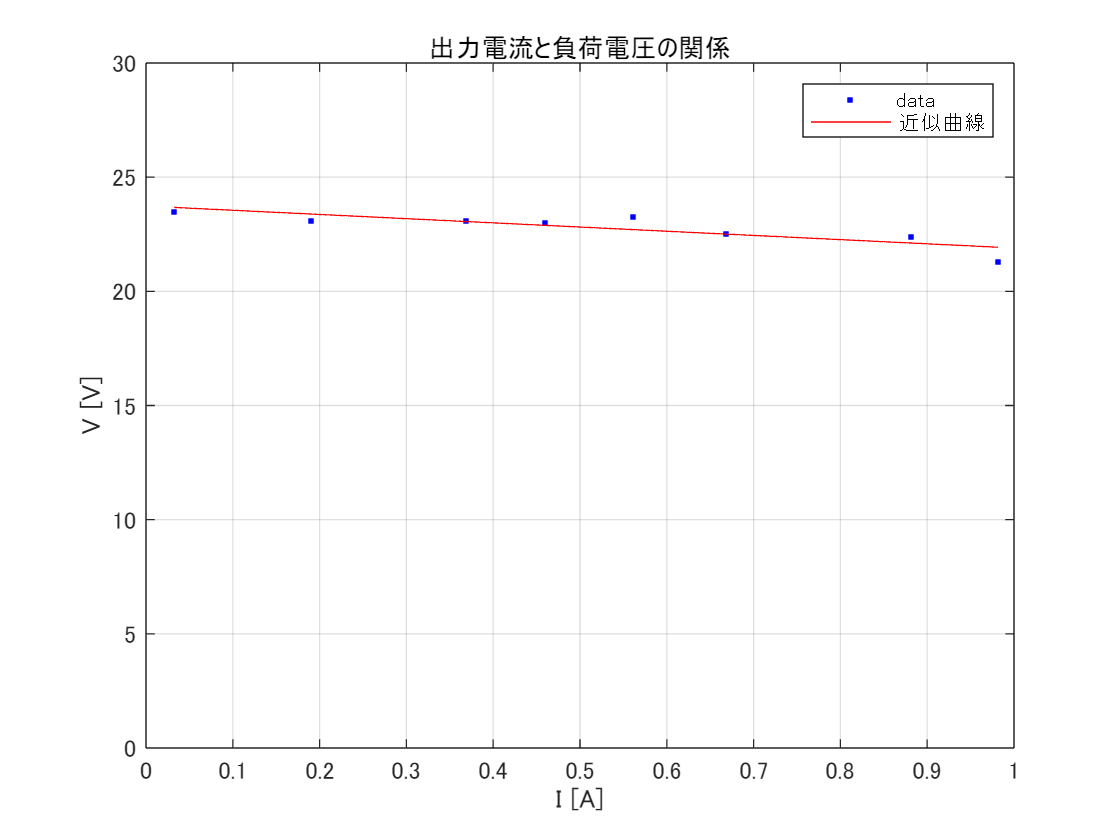

fig = figure;
ax = gca;
plot(reg,x,y)
title("出力電流と負荷電圧の関係");
xlabel("I [A]");
ylabel("V [V]");
ax.XLim = [0,1];
ax.YLim = [0,30];
grid on

drawnow

function y = load_voltage(current)
%
%  電源モデル
%  出力電流と負荷電圧の関係
%

% 電源電圧
source_voltage = 24; % [V]

% 内部抵抗
internal_register = 2; % [Ω]

% 負荷電圧
y = source_voltage - internal_register * current;
end